# Fig 5e 5f

**Load data**

clear
[file_loc] = fileparts(matlab.desktop.editor.getActiveFilename);
cd(file_loc);
dataDir = '..\..\FINAL DATA files';
load([dataDir filesep 'F051_data.mat'],'S','settings','allIF');

conditions = settings.conditions


framesPerHr = 60/12;

frameEdU = 0;
timeStart = 0;

folding =5;

numFrames = size(S(1).area,2);
xFrames = 1:numFrames;
xTime = (xFrames-1)./framesPerHr;

times = arrayfun(@(x)(numFrames - x.POI)/framesPerHr,S,'UniformOutput',false);
[S.POI_time] = times{:};

for i = 1:length(S)
    S(i).frameDrugAdded = 1;
    S(i).POI_realtime = S(i).POI/framesPerHr;
    S(i).POI_drug_time = ( S(i).frameDrugAdded - S(i).POI)/framesPerHr;
    S(i).drug_time = S(i).frameDrugAdded/framesPerHr;
end

ALL_row = [1:8];

**Gate cells**

xthresh = 2.5e6;
xrange = linspace(0,4e6,1000);
for i = 1:length(allIF)
    xdata = allIF(i).DNA;
    [f, xi] = ksdensity(xdata,xrange);
    
    xi_trunc = xi(xi<xthresh);
    f_trunc = f(xi<xthresh);
    [~, maxi] = max(f_trunc);
    N_peak = xi_trunc(maxi);
    S(i).DNA_peak = N_peak;
end

**Gate cells**

for i = 1:length(S)
    
    dat = S(i);
    apcExpressGate = false(length(dat.POI(:,1)),1);

    for n = 1:length(dat.POI(:,1))
        if dat.POI(n,1) > 1 * framesPerHr & dat.POI(n,1) < numFrames - 1 * framesPerHr
            apcExpressGate(n) = nanmean(dat.apcAreaNormM(n,dat.POI(n,1) + [-1* framesPerHr: -.5* framesPerHr] )) > .5 & ...
                nanmean(dat.apcAreaNormM(n,dat.POI(n,1) + [round(.5* framesPerHr): 1* framesPerHr] )) < .05;
        end
      
        
    end
    S(i).apcExpressGate = apcExpressGate;
 
end


**5e, 5f, s7a**

ans = 6183

ans = 1792

ans = 2337

ans = 1009

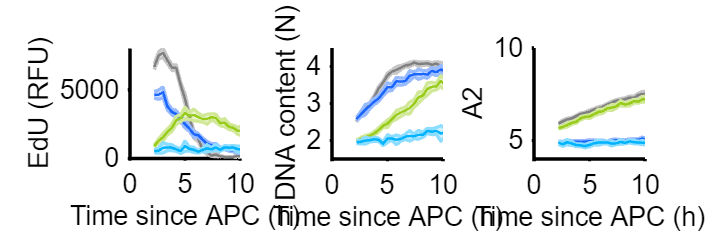

ans = 7421

ans = 2424

ans = 2667

ans = 1245

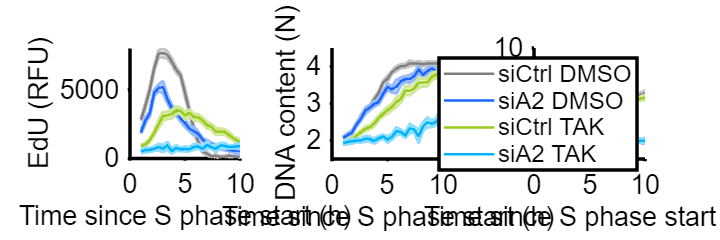

conds=[1 3  11 13 ] ;
poi_list = [2 3];


gateVals = {{},{},{},{},{},{},{},{}};
rangeVals = {{[]},{[]},{[]},{[]},{[]},{[]},{[]},{[]}};
name = {'APC' 'S phase start'};
edges = (0:(2/framesPerHr):15);
lims = {[0 10],[0 10]};
gate_row = ALL_row;

name_scatter = [];
name_mean =  [pwd() 'siA2_mean'];



plot_IF_linear_gateA2_save(poi_list, conds, S, gateVals, rangeVals, edges, lims, name, conditions, gate_row,1, name_scatter, name_mean);

function plot_IF_linear_gateA2_save(poi_list, conds, S, gateVals, rangeVals, edges, lims, name, conditions, row_gate, gateA2, save_scatter, save_mean)
colors = [.5 .5 .5 ;.1 .4 1;.6 .8 .1; 0 .7 1];
for p = 1:length(poi_list)
    poiAligned=poi_list(p);
 
    f1 = figure('units','inches','pos',[0 0 4*3 4 ]);
  
    
    legend_names = {};
    for i=1:length(conds)
        
        ind= any(S(conds(i)).fixedRow == row_gate,2) & ~isnan(S(conds(i)).dna) & ~isnan(S(conds(i)).POI_time(:,poiAligned)) & S(conds(i)).apcExpressGate   & ...
            gate_vals(S(conds(i)), gateVals{i}, rangeVals{i}) ;
        if gateA2 & (conds(i) == 3 | conds(i) == 13)
            ind = ind & S(conds(i)).YFP2 < 2^5.5;
        end
        xdata = S(conds(i)).POI_time(ind,poiAligned);
        ydata = [];
        ydata(:, 1) = (S(conds(i)).FarRed1(ind));
        ydata(ydata(:,1) < .1,1) = .1;
        ydata(:,1) = (ydata(:,1));
        ydata(:, 2) = 2*(S(conds(i)).dna(ind)/S(conds(i)).DNA_peak);
        ydata(:, 3) = log2(S(conds(i)).YFP2(ind));
        
                ind = xdata >= lims{p}(1) & xdata <= lims{p}(2);
        xdata = xdata(ind);
        ydata = ydata(ind,:);
        sum(ind)
      
        [binData, edges] = bin_xy(xdata, ydata, {'mean','median','std'},...
            'Edges',edges);
        midpoints = edges + (edges(2) -edges(1))/2;
        midpoints = midpoints(1:end-1);
    
  
        
        bin_gate = binData(2).numCells > 5;
        figure(f1)
        subplot(1,3,1)
        hold on
         shadedErrorBar(midpoints(bin_gate), binData(1).mean(bin_gate), 2*binData(1).std(bin_gate)./sqrt(binData(1).numCells(bin_gate)),'lineProps',{'Color',colors(i,:),'LineWidth',1.5})
      
        xlabel(['Time since ' name{p} ' (h)']);
        ylabel('EdU (RFU)');
        xlim(lims{p});
        ylim([0 8000])
        axis square
        
        subplot(1,3,2)
        hold on
     
         shadedErrorBar(midpoints(bin_gate), binData(2).mean(bin_gate), 2*binData(2).std(bin_gate)./sqrt(binData(2).numCells(bin_gate)),'lineProps',{'Color',colors(i,:),'LineWidth',1.5})
    
        xlabel(['Time since ' name{p} ' (h)']);
        ylabel('DNA content (N)');
        xlim(lims{p});
        ylim([1.5 4.5])
        axis square
        
        subplot(1,3,3)
        hold on
      
         shadedErrorBar(midpoints(bin_gate), binData(3).mean(bin_gate), 2*binData(3).std(bin_gate)./sqrt(binData(3).numCells(bin_gate)),'lineProps',{'Color',colors(i,:),'LineWidth',1.5})
    
        xlabel(['Time since ' name{p} ' (h)']);
        ylabel('A2');
        xlim(lims{p});
        ylim([4 10])
        axis square
        
        if length(midpoints(bin_gate)) > 1
            legend_names = [legend_names, conditions(conds(i),1)];
        end
        
        
        
    end
   
end


       legend(legend_names)
    if ~isempty(save_mean)
        print_pdf([save_mean '_' name{p} '.pdf'])
    end
end
